# **Reto 1** 

# Profundización 1 Electromedicina

Hamilton Hernández - 219160360

Andres Peña - 216160223

Santiago Quiroz - 218160293

# **Restauración de señales de ECG de personas**

clear variables
close all
clc
warning('off','all');

## Señal desde Base de Datos

Se carga la señal ECG de la base de datos propuesta

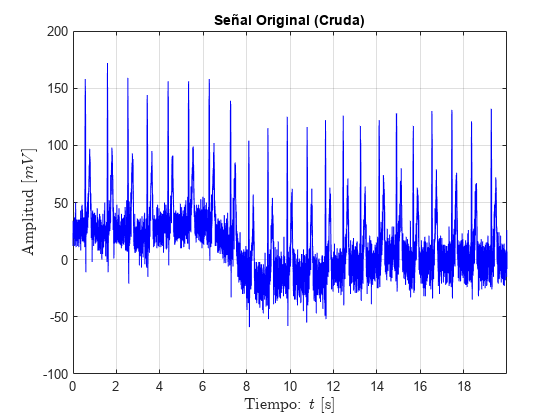

ECG_load = fopen("ecg\Person_82\rec_1.dat","r");
ECG_read = fread(ECG_load,inf,'*int16');
ECG_r = double(ECG_read(1:2:end));
ECG_f = double(ECG_read(2:2:end));
fs = 500;
ts = 1/fs;
L = length(ECG_r);
t = (0:L-1)*ts;

%-----------------Grafico Señal Original-------------
figure;
set(gcf,'color','w');
plot(t,ECG_r,'b');
title("Señal Original (Cruda)");
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

## Fourier

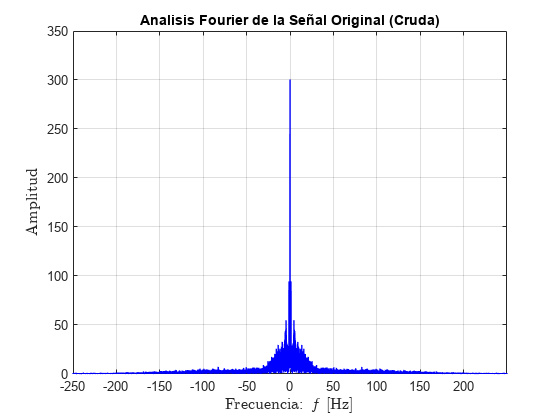


[f,ECG_fourier_r] = fourier(ECG_r,fs); 

%-----------------Analisis de fourier--------------
figure;
set(gcf,'color','w');
plot(f,ECG_fourier_r,'b','LineWidth',1);
title("Analisis Fourier de la Señal Original (Cruda)");
grid on;
xlim([f(1),f(end)]);
xlabel('Frecuencia: $f$ [Hz]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud','FontSize',12,'Interpreter','latex');

Tras realizar el analisis de Fourier se observan componentes de ruido en los 50 Hz, también se pude ver la componente DC y algunas componentes de alta frecuencia que deberán ser filtradas posteriormente.

## Filtro Notch Óptimo

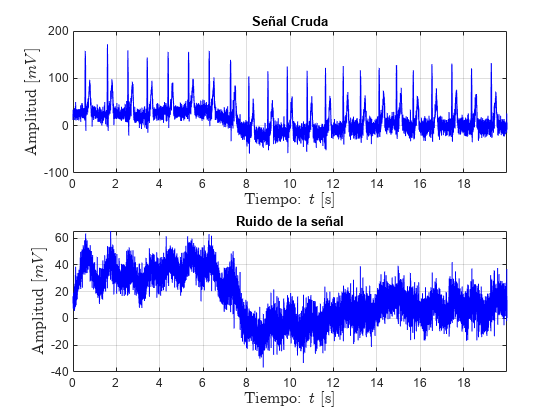

ruido1 = fbutt(ECG_r,46,fs,'high',6);
ruido2 = fbutt(ECG_r,1,fs,'low',4);
ruido = ruido1+ruido2;
[~,ruido_fourier] = fourier(ruido,fs);

%-----------------Grafico Del ruido--------------
%Original
figure;
set(gcf,'color','w');
subplot(2,1,1)
plot(t,ECG_r,'b');
title("Señal Cruda")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

%Ruido
subplot(2,1,2)
plot(t,ruido,'b');
title("Ruido de la señal")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

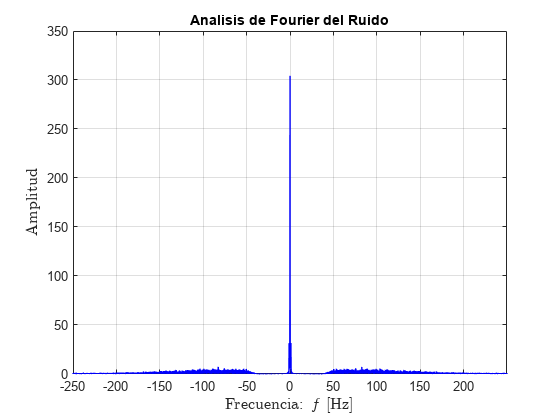

%-----------------Analisis de fourier--------------
figure;
set(gcf,'color','w');
plot(f,ruido_fourier,'b','LineWidth',1);
title("Analisis de Fourier del Ruido");
grid on;
xlim([f(1),f(end)]);
xlabel('Frecuencia: $f$ [Hz]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud','FontSize',12,'Interpreter','latex');

Ahora calculamos la función de ponderación y se aplica el filtro de notch optimo

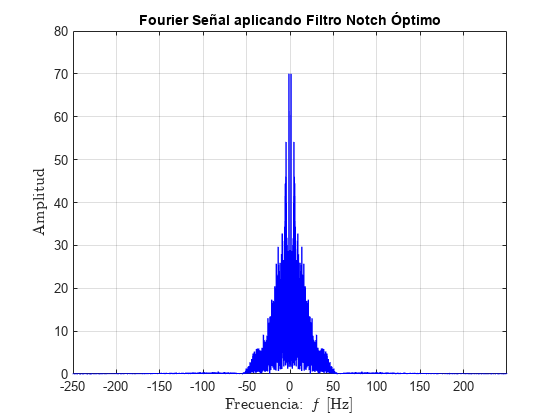

ECG_estimada = notch_optimo(ECG_r,ruido);
[~,ECG_estimada_fourier] = fourier(ECG_estimada,fs);

%-----------------Analisis de fourier--------------
figure;
set(gcf,'color','w');
plot(f,ECG_estimada_fourier,'b','LineWidth',1);
title("Fourier Señal aplicando Filtro Notch Óptimo");
grid on;
xlim([f(1),f(end)]);
xlabel('Frecuencia: $f$ [Hz]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud','FontSize',12,'Interpreter','latex');

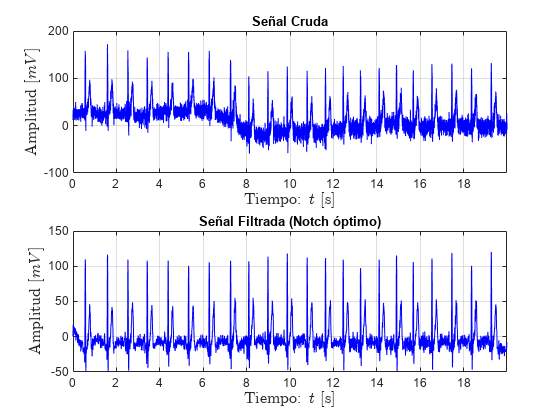

%-----------------Grafico aplicando filtro notch óptimo--------------
%Original
figure;
set(gcf,'color','w');
subplot(2,1,1)
plot(t,ECG_r,'b');
title("Señal Cruda")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

%Filtrada 
subplot(2,1,2)
plot(t,ECG_estimada,'b');
title("Señal Filtrada (Notch óptimo)")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

## Envolvente de la Señal

Primero normalizamos la señal ECG_highpass y posteriormente obtenemos su envolvente

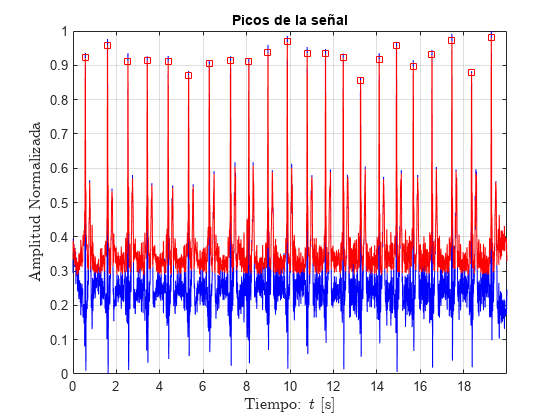

ECG_estimada_normal = normalizar(ECG_estimada);
[env_ecg_sup,env_ecg_inf] = envelope(ECG_estimada_normal,5,"rms");
[pks,locs] = findpeaks(env_ecg_sup,'MinPeakHeight',0.5,'MinPeakDistance',0.5*fs);


%-----------------Grafico Señal normalizada aplicando envolvente y encontrando picos--------------
%Estimada normalizada
figure;
set(gcf,'color','w');
plot(t,ECG_estimada_normal,'b');
hold on;
%Envolvente de la Estimada
plot(t,env_ecg_sup,'r');
plot(t(locs),pks,"sr");
hold off

title("Picos de la señal")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud Normalizada','FontSize',12,'Interpreter','latex');

## **Segmentación de la Señal:**

Se procede a realizar la segmentación y luego graficar una sola señal que es el resultado del promedio todos los segmentos, esta señal tiene una longitud del promedio de las longitudes entre pico y pico.

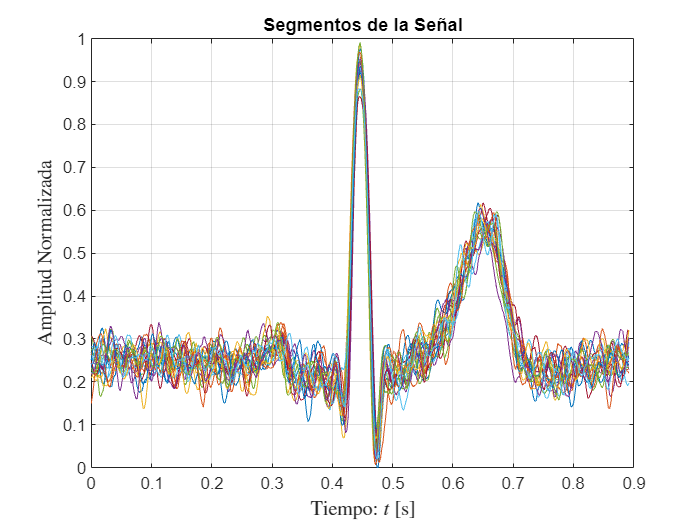

L_segmento=round(mean(diff(locs))/2);

for i=2:length(pks)-1
    segmentos(i-1,:)=ECG_estimada_normal(locs(i)-L_segmento:locs(i)+L_segmento);
end

%-----------------Grafico de todos los ciclos segmentados--------------
figure;
set(gcf,'color','w');
plot(t(1:L_segmento*2+1),segmentos');
title("Segmentos de la Señal")
grid on;
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud Normalizada','FontSize',12,'Interpreter','latex');

Ahora se encuentra el promedio de las señales para crear una señal promedio

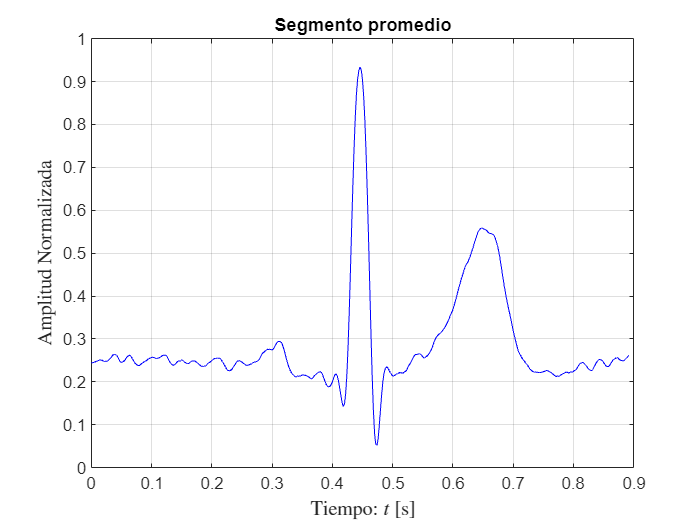

sig_promedio=sum(segmentos)/length(segmentos(:,1));

%-----------------Grafico del promedio de los segmentos--------------
figure;
set(gcf,'color','w');
plot(t(1:L_segmento*2+1),sig_promedio,'b');
title("Segmento promedio")
grid on;
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud Normalizada','FontSize',12,'Interpreter','latex');

# **Restauración de imágenes de leucocitos de un canino**  

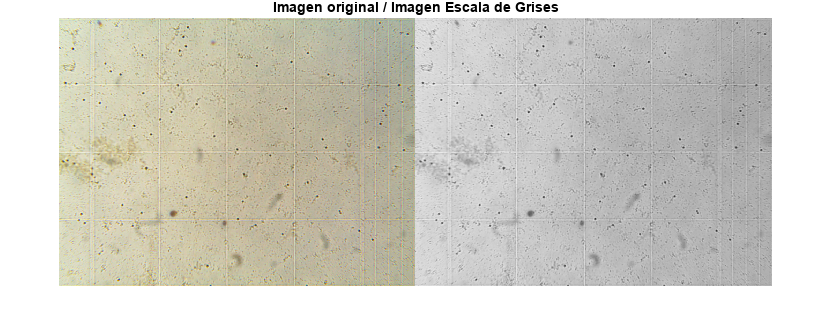

clear variables
close all
clc
% warning('off','all');

% Cargar una imagen de ejemplo
imagen = imread('img\S2_1.bmp');

% Convertir la imagen a escala de grises si es necesario
if size(imagen, 3) > 1
    imagen_gray = rgb2gray(imagen);
end

% imagen_gray = imagen(:,:,3);

% Mostrar la imagen original y la imagen en escala de grises
figure;
Graficar(imagen,imagen_gray,"Imagen original / Imagen Escala de Grises");

## Aplicando la transformada de fourier

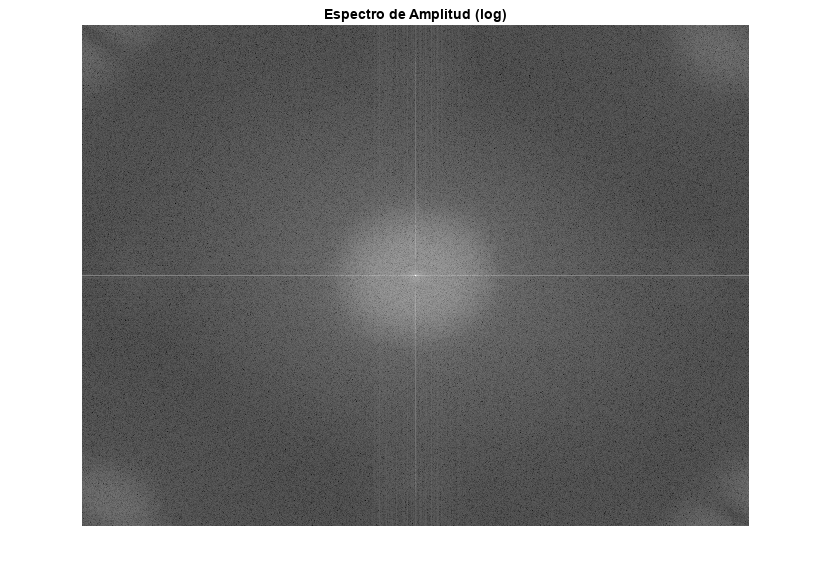

% Aplicar la transformada de Fourier 2D
transformada = fft2(imagen_gray);

% Mover el cero al centro de la transformada
transformada_centralizada = fftshift(transformada);

% Calcular el espectro de amplitud
espectro = log(1+abs(transformada_centralizada));
% Mostrar el espectro de amplitud en escala logarítmica
figure;
imshow(espectro, []);
title('Espectro de Amplitud (log)');

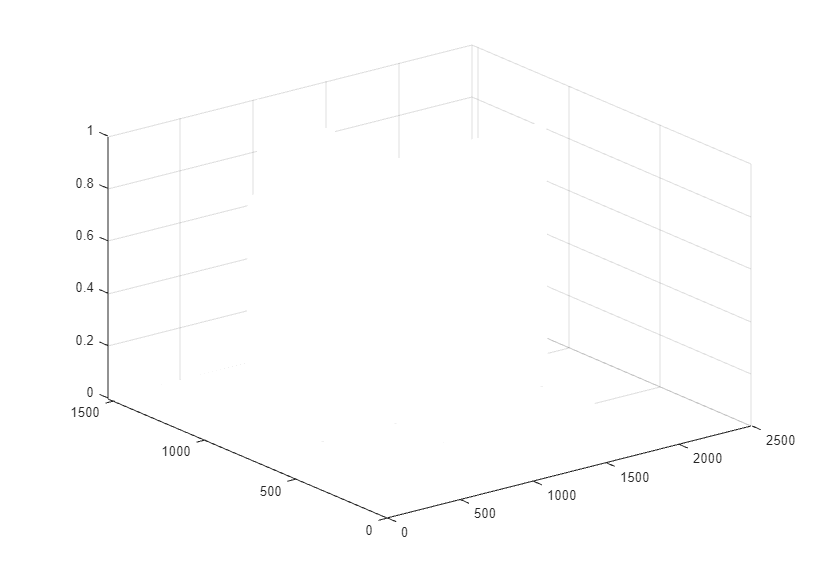

[m,n] = size(espectro);
ancho_gaussiana=4;
x=gaussiana(0:m-1,round(m/2),ancho_gaussiana);
x=x/max(x);
x=x';
y=gaussiana(0:n-1,round(n/2),ancho_gaussiana);
y=y/max(y);
im_fil=x+y;

%Elimina el pico en la interseccion de las dos gaussianas
for i=1:m-1
    for j=1:n-1
        if(im_fil(i,j)>1)
            im_fil(i,j)=1;  
        end
    end
end
mesh(im_fil);

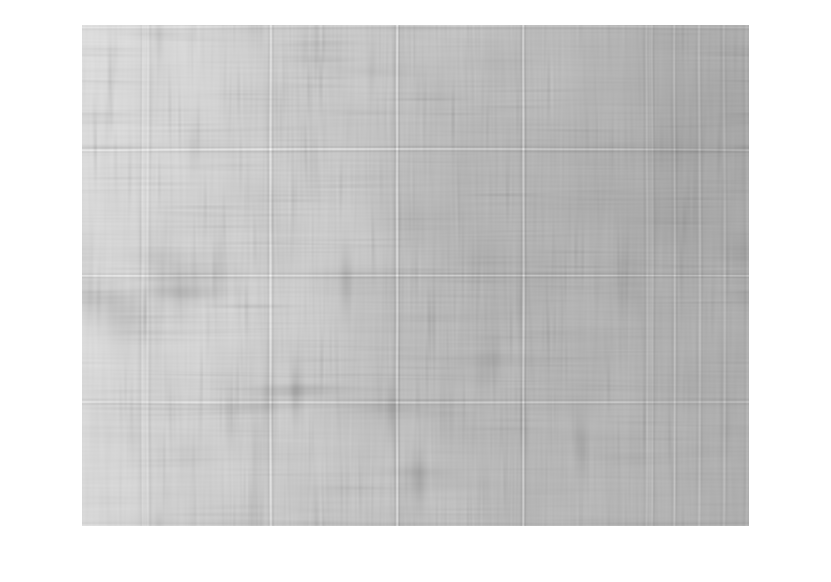

ruido = uint8(real(ifft2(ifftshift(im_fil.*transformada_centralizada))));
imshow(ruido);

filtrada = notch_optimo(imagen_gray,ruido,1,1);

filas: 1536 Columnas: 2048
Factor = 1.0177


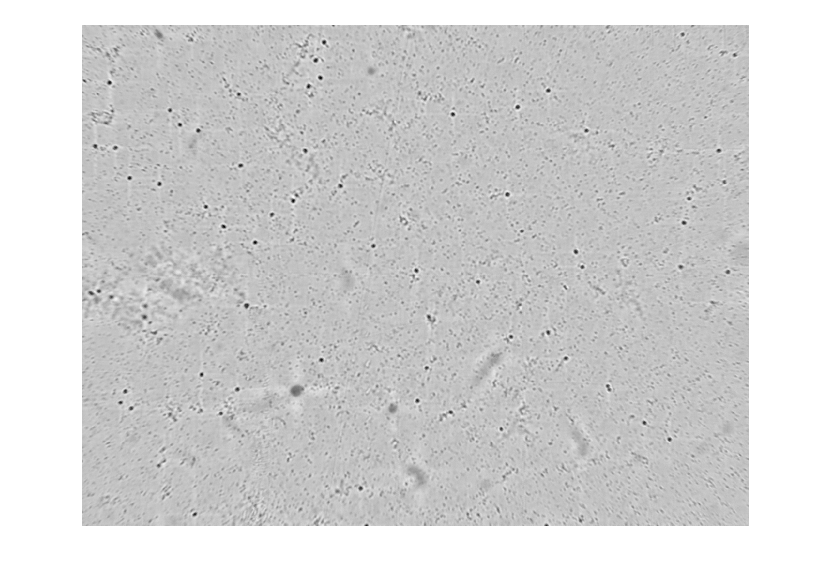

imshow(filtrada,[]);

## Filtro Wiener

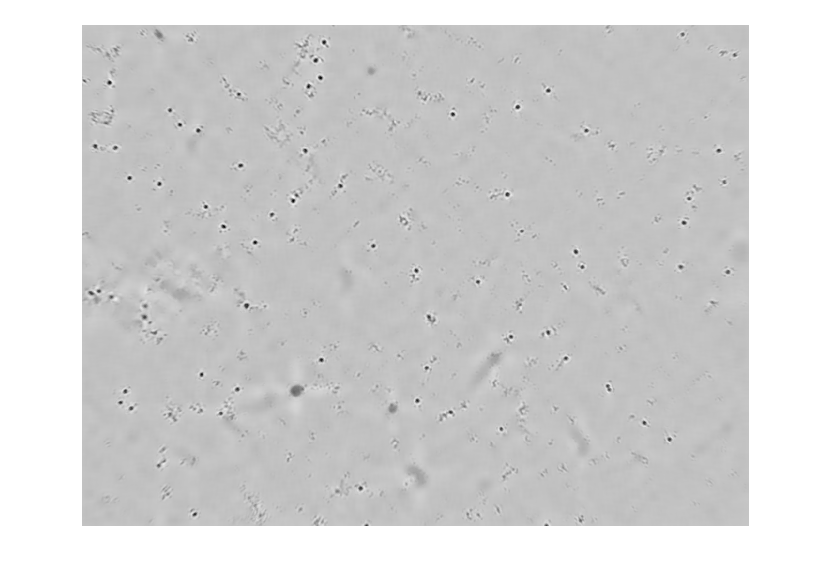

Xw=32;
Yw=32;
[If, ruido]=wiener2(filtrada,[Xw,Yw]);
imshow(If,[]);